# Assignment 4 : Compartment Modelling

**Part 1**

**1.**

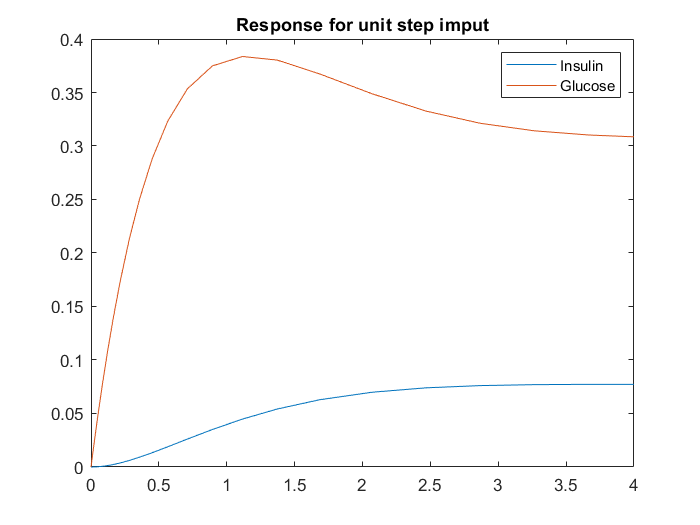

[t,y]=ode23('bolus0',[0 4],[0 0]);
plot(t,y)
title('Response for unit step imput');
legend('Insulin','Glucose');

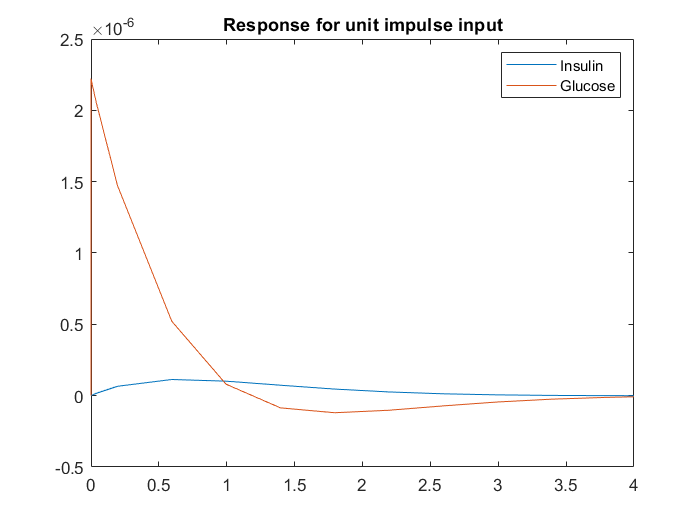

[t,y]=ode23('bolus1',[0 4],[0 0]);
plot(t,y);
title('Response for unit impulse input');
legend('Insulin','Glucose');

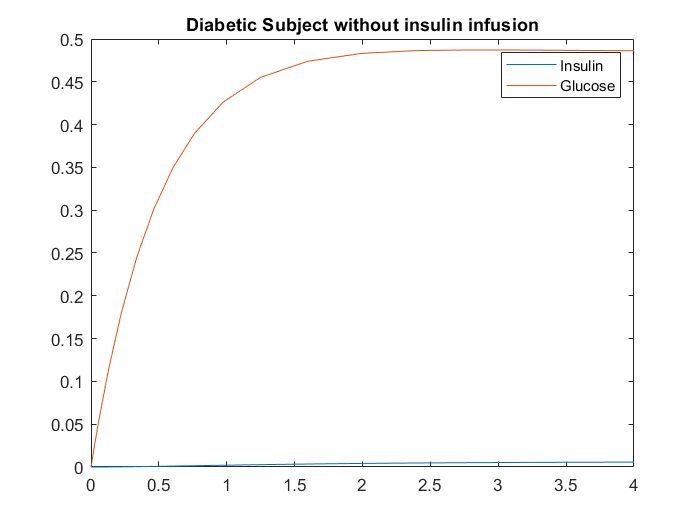

[t,y]=ode23('bolus2',[0 4],[0 0]);
plot(t,y);
title('Diabetic Subject without insulin infusion');
legend('Insulin','Glucose');

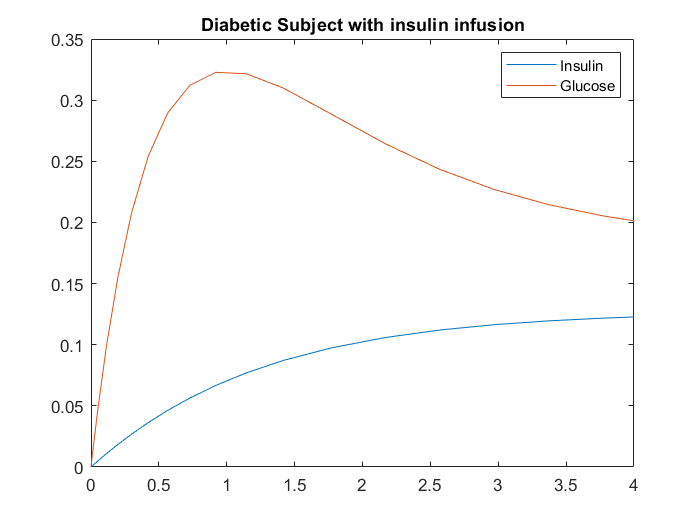

[t,y]=ode23('bolus3',[0 4],[0 0]);
plot(t,y);
title('Diabetic Subject with insulin infusion');
legend('Insulin','Glucose');

2.

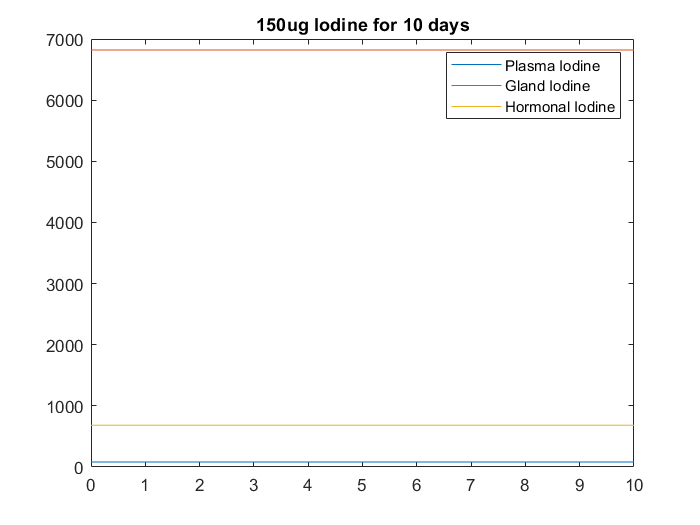

[t,y] = ode23('riggs150',[0 10],[81.2 6821 682]);
plot(t,y);
title('150ug Iodine for 10 days');
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine');

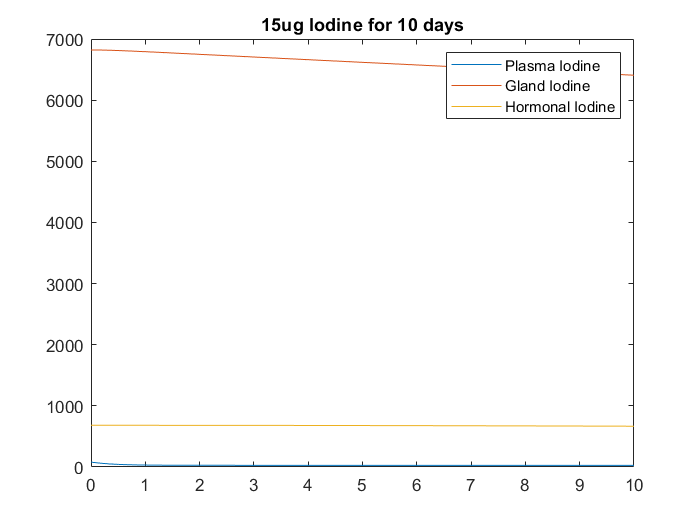

[t,y] = ode23('riggs15',[0 10],[81.2 6821 682]);
plot(t,y);
title('15ug Iodine for 10 days');
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine');

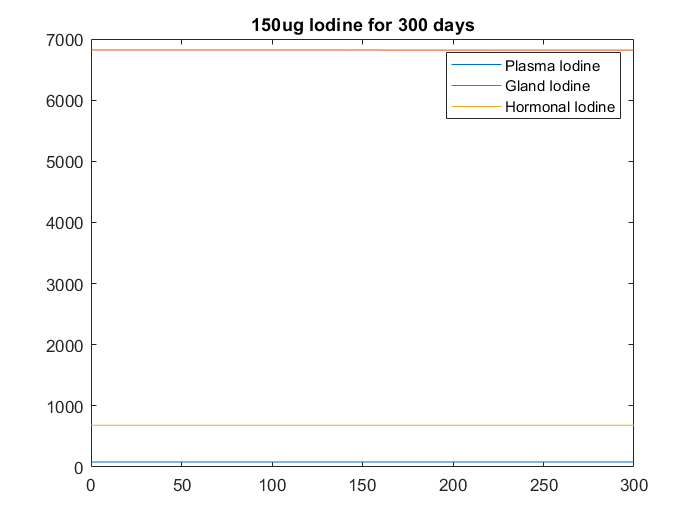

[t,y] = ode23('riggs150',[0 300],[81.2 6821 682]);
plot(t,y);
title('150ug Iodine for 300 days');
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine');

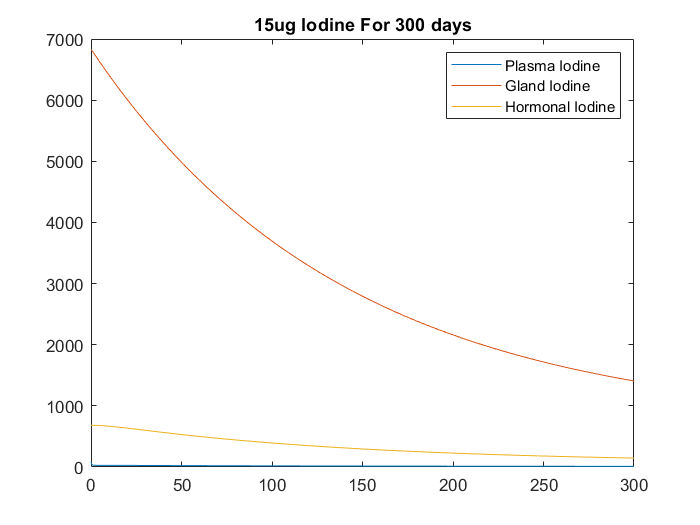

[t,y] = ode23('riggs15',[0 300],[81.2 6821 682]);
plot(t,y);
title('15ug Iodine For 300 days');
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine');

a. Hypothyroidism due to autoimmune thyroid disease - We need to change parameter K2 to simulate autoimmune thyroid disease. Therefore, K2 is  reduced from 0.01 to 0.005. 

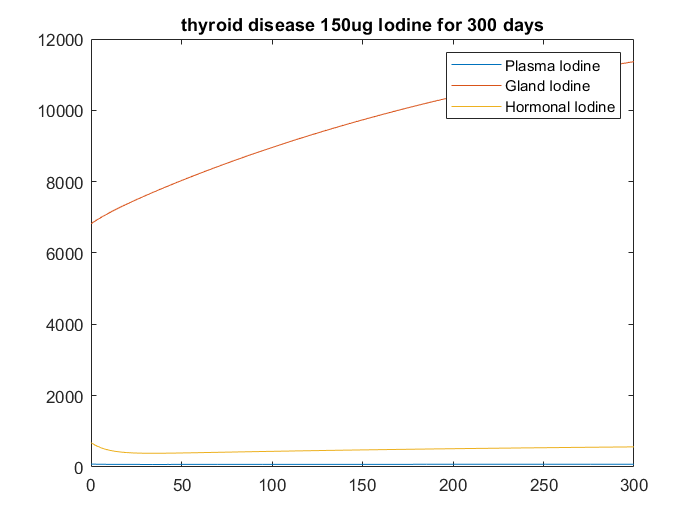

[t,y] = ode23('riggs150a',[0 300],[81.2 6821 682]);
plot(t,y);
title('thyroid disease 150ug Iodine for 300 days');
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine');

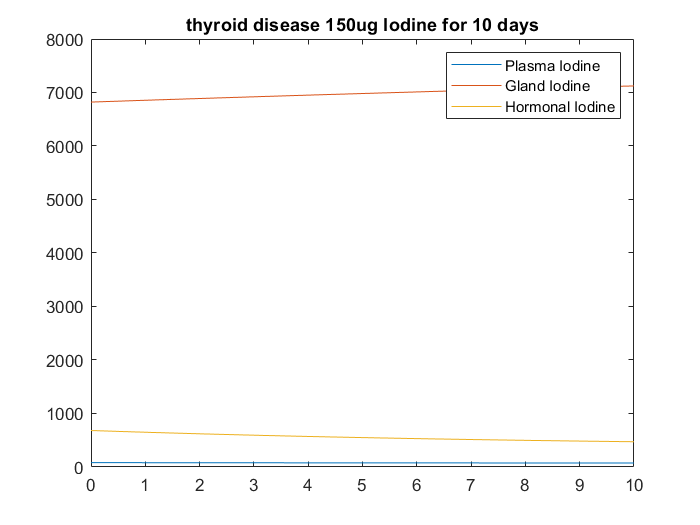

[t,y] = ode23('riggs150a',[0 10],[81.2 6821 682]);
plot(t,y);
title('thyroid disease 150ug Iodine for 10 days');
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine');

b. Hypothyroidism due to low Iodine intake 

Reduce the iodine intake B1(t) from 150ug per day to a lower value. graphs have already been plotted.

c. Hyperthyroidism due to Grave’s disease This disease is a condition where thyroid hormone is over produced. To model this one we need to change  the K2 parameter of the rigs model. new K2 value be 0.1 under normal conditions.

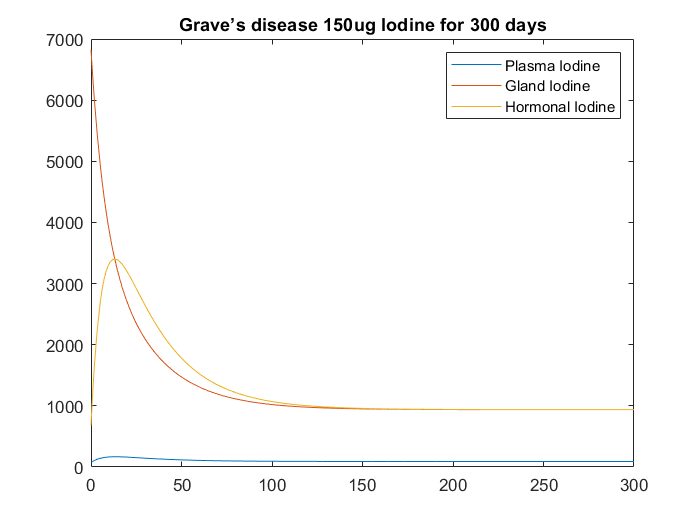

[t,y] = ode23('riggs150c',[0 300],[81.2 6821 682]);
plot(t,y);
title('Grave’s disease 150ug Iodine for 300 days');
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine');

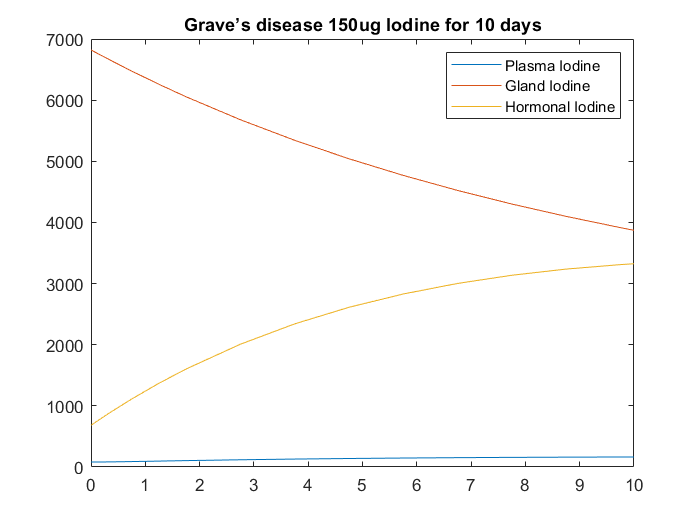

[t,y] = ode23('riggs150c',[0 10],[81.2 6821 682]);
plot(t,y);
title('Grave’s disease 150ug Iodine for 10 days');
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine');

d. Common causes of goitre and tumors and how can they be simulated in the Riggs' model?

A goitre is a lump or swelling at the front of the neck caused by a swollen thyroid. Lack of iodine  intake causes this disease. Iodine intake has been reduced to 50ug per day. 

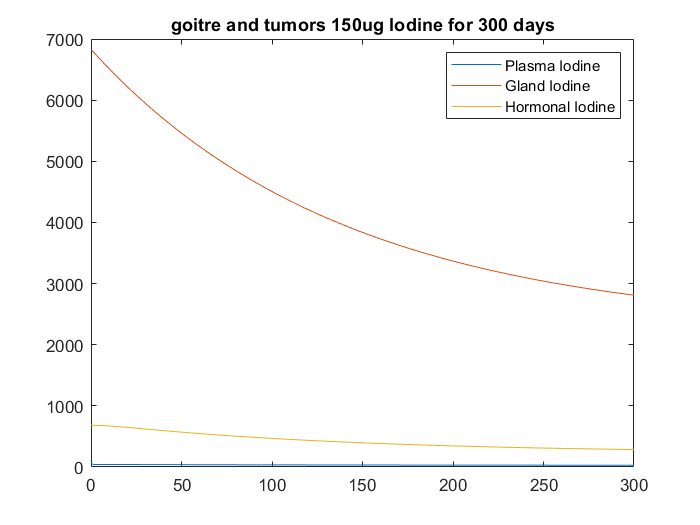

[t,y] = ode23('riggs50d',[0 300],[81.2 6821 682]);
plot(t,y);
title('goitre and tumors 150ug Iodine for 300 days');
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine');

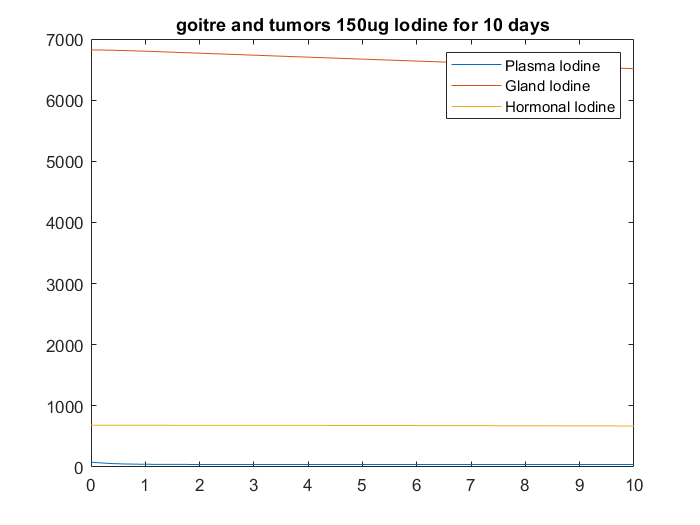

[t,y] = ode23('riggs50d',[0 10],[81.2 6821 682]);
plot(t,y);
title('goitre and tumors 150ug Iodine for 10 days');
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine');

**Part 3**

**1.**

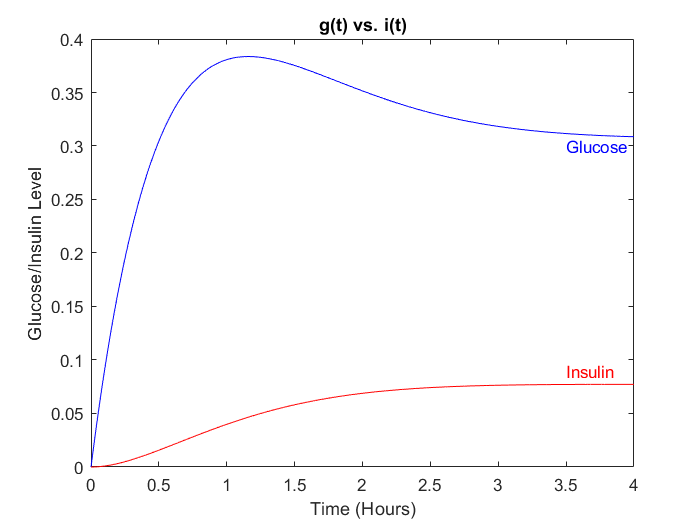

t = [0:0.001:4];
g_t = (exp((-1.4).*t)).*(-(4/13)*cos((0.8).*t) + (37/52)*sin((0.8).*t)) + 4/13;
i_t = (exp((-1.4).*t)).*(-(1/13)*cos((0.8).*t) - (7/52)*sin((0.8).*t)) + 1/13;

figure
plot(t, g_t, 'b', t, i_t, 'r');
title('g(t) vs. i(t)');
xt = [3.5 3.5];
yt = [0.3 0.09];
str = {'Glucose','Insulin'};
text(xt(1), yt(1), str(1), 'Color','blue')
text(xt(2), yt(2), str(2), 'Color','red')
xlabel('Time (Hours)');
ylabel('Glucose/Insulin Level');

2.

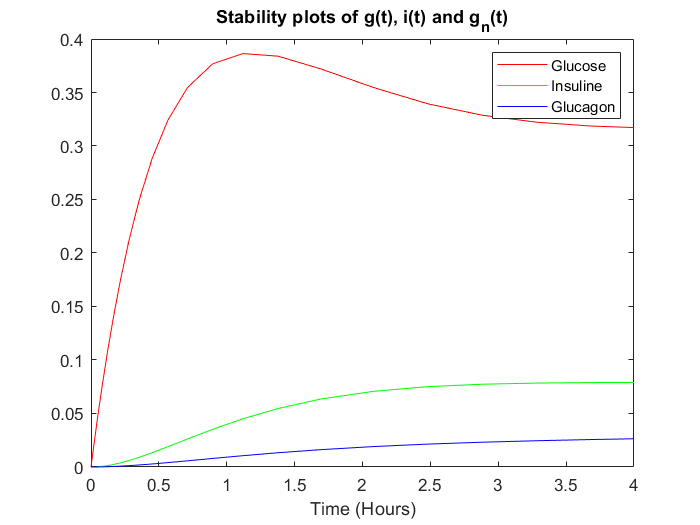

[t,y] = ode23('glucagon_model',[0 4],[0 0 0]);
k = length(y);
plot(t, y(1:1:k), 'r-', t, y((k+1):1:2*k), 'g-', t, y((2*k+1):1:3*k), 'b');
xlabel('Time (Hours)');
title('Stability plots of g(t), i(t) and g_n(t)');
legend ('Glucose', 'Insuline', 'Glucagon');